#               Diseño de Filtros digitales

#         Tema A1 - Primer Recuperatorio 

clc;close all;clear;

**Se dispone de un filtro analógico cuya transferencia **$H(s)$** es**

                                             
$$H_a(s) = \frac{s + 0,1 }{(s + 0,1)^2 + 9}$$
  

**Se desea convertir este filtro a un filtro digital que procese señales muestreadas con un período de muestreo **$T = 0,1s$**.**

**1.Primero, utilice la transformación bilineal para obtener **$H_{bilin}(z)$** y determine si este filtro es FIR o IIR. **

                         *Discretizacion Resp.Impulso:*   $h(n) = h_a(t)|_{t = nT} = h_a(nT)$

                                                  El mapeo es :        $z = \frac{1 + sT/2}{1 - sT/2}$

%Para entender mejor primero lo defino en continua:
s = tf('s');
Ha = (s+0.1)/((s+0.1)^2 + 9)

Ha =
 
       s + 0.1
  ------------------
  s^2 + 0.2 s + 9.01
 
Continuous-time transfer function.



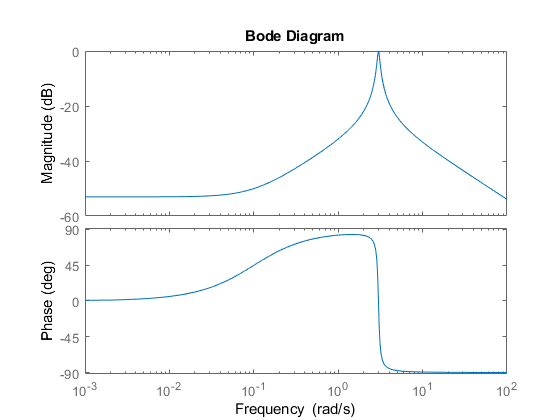

bode(Ha/10^(13.95/20))

%Luego lo discretizo con el metodo bilineal(tustin).
%DW = abs(2.904 - 3.104) = 0.2 % (rad/s) 
ts = 0.1; %s
H_bilin = c2d(Ha, ts, 'tustin')

H_bilin =
 
  0.04867 z^2 + 0.0004842 z - 0.04818
  -----------------------------------
        z^2 - 1.893 z + 0.9806
 
Sample time: 0.1 seconds
Discrete-time transfer function.



-  Si se parte de Ha(s), la elección de T sí influye. T debe ser tal que la compresión de ω sea lo menor posible, Para ello, las bandas relevantes del filtro deben estar cerca del origen

                LOS CEROS NO QUEDAN MAPEADOS DEL MISMO MODO

# Preguntar como decido el T, tengo datos de dW.

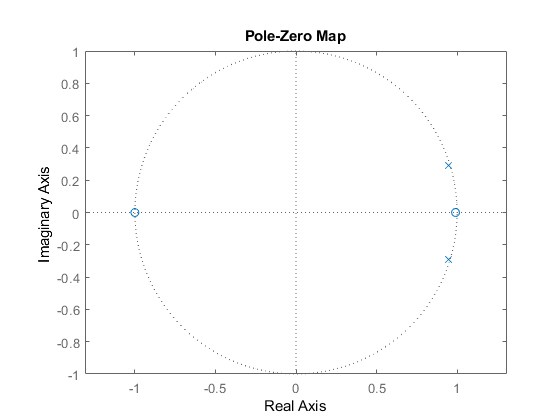


%veamos mediante los el pzmap para ver que tipo de filtro es:
pzmap(H_bilin)
axis('equal')

Desde ya se ve que tiene polos y ceros, pero los polos no están en el origen por lo que es un filtro $IIR$, esto se esperaba viendo la forma en continua, aunque los polos son estables dado que se encuentran dentro del circulo unidad. tiene un cero en $z=-1$ y otro en $z=0.99$ con plos y polos en $z \approx 0.95 \pm 0.3$

**2. Ahora utilice la transformación de invarianza al impulso para obtener **$H_{imp}(z)$** y determine nuevamente si obtiene un filtro FIR o IIR. **

- Si T (ts) es demasiado grande, vamos a sufrir efectos de aliasing. La elección de T debe estar en concordancia con el ancho de la banda pasante, pero también debe tener en cuenta el ancho de la banda de transición para evitar aliasing perjudicial al momento de la discretización. 

- Si T es demasiado chico, puede haber una compresión innecesaria del espectro.

                         *Discretizacion Resp.Impulso:*   $h(n) = h_a(t)|_{t = nT} = h_a(nT)$

                                                  El mapeo es :        $z = e^{sT}$

H_imp = c2d(Ha, ts, 'impulse')

H_imp =
 
   0.1 z^2 - 0.09458 z
  ----------------------
  z^2 - 1.892 z + 0.9802
 
Sample time: 0.1 seconds
Discrete-time transfer function.



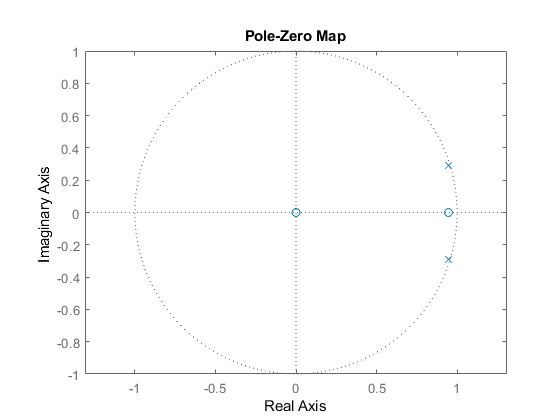


%veamos mediante los el pzmap para ver que tipo de filtro es:
pzmap(H_imp)
axis('equal')

Tambien es un filtro $IIR$ en donde hay cero en el origen a diferencia del anterior donde habia un cero en $z=-1$

**3. Compare los diagramas de polos y ceros obtenidos en ambos casos y obtenga conclusiones con respecto a cómo se actúan las dos transformaciones anteriores sobre los polos y ceros de **$H_a(s)$**. **

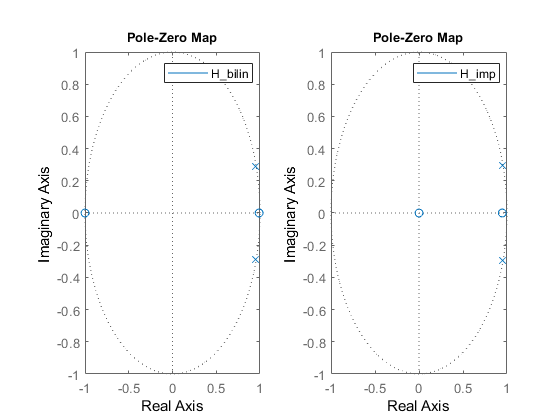

figure()
subplot(1,2,1)
    pzmap(H_bilin)
    legend("H_{bilin}")
subplot(1,2,2)
    pzmap(H_imp)
    legend("H_{imp}")

La diferencia obvia es que en con el metodo de discretizacion bilineal( o tustin) aparece un cero en altas frecuencias($z=-1 -> s->\infty$) y en el metodo de invarianza al impulso aparece un cero en el origen

($z=0 -> z=-\infty$)

podemos sospechar ya que en el metodo de resp. imp. tenga Aliasing por lo que el tiempo de muestreo estaria mal elegido. y de ahi las diferencias, de hecho el tiempo de muestreo es muy importante, aunque con el metodo bilineal tambien pues puede estar mal elegido el ts y w puede estar muy comprimido